disp("Question 1")

Question 1


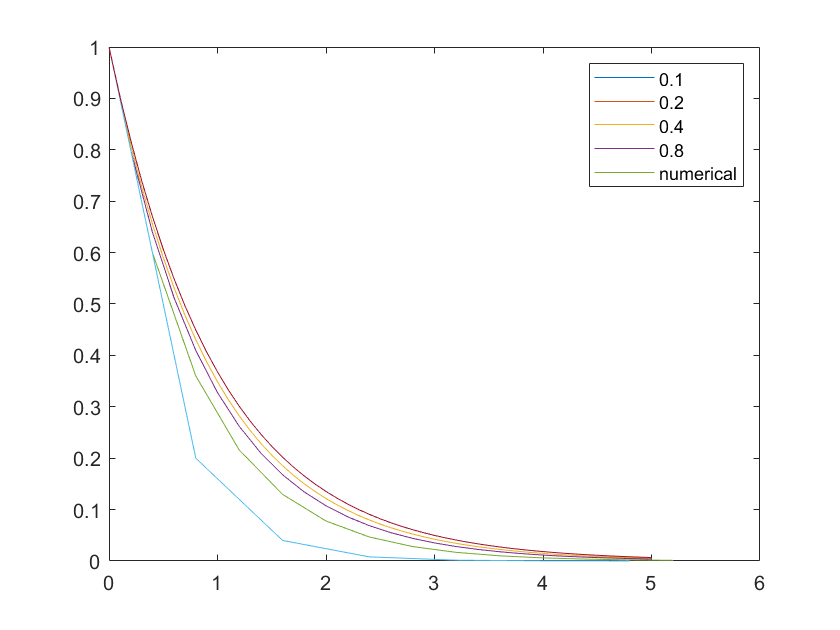

dt = [0.1, 0.2, 0.4, 0.8];
for i = 1:length(dt)
    [T, Y] = euler1stOrder(1, @deriv, dt(i), 5);
    plot(T, Y);
    hold on
end
t = 0:0.1:5;
plot(t, exp(-t));
legend('0.1', '0.2', '0.4', '0.8', 'numerical');

disp(" ")

disp("Question 4")

Question 4



syms x y;
Q4_1 = simplify(sin(x)^2+cos(x)^2)

$$Q4\_1 = 1$$

Q4_2 = simplify(sin(x)*cos(y)+sin(y)*cos(x))

$$Q4\_2 = \sin\left(x+y\right)$$

Q4_3 = simplify(cosh(x)^2-sinh(x)^2)

$$Q4\_3 = 1$$

disp(" ")

disp("Question 5")

Question 5


syms a b c A m
Q5_1 = solve(a^2==b^2+c^2-2*b*c*cos(A), b)

$$Q5\_1 = \left(\begin{array}{c} c\,\cos\left(A\right)+\sqrt{a^{2}+c^{2}\,{\cos\left(A\right)}^{2}-c^{2}}\\ c\,\cos\left(A\right)-\sqrt{a^{2}+c^{2}\,{\cos\left(A\right)}^{2}-c^{2}} \end{array}\right)$$

Q5_2 = solve(subs(a^2==b^2+c^2-2*b*c*cos(A), [a c A], [5*m 2*m 60*pi/180]), b)

$$Q5\_2 = \left(\begin{array}{c} m+\sqrt{22}\,m\\ m-\sqrt{22}\,m \end{array}\right)$$

disp(" ")

disp("Question 6")

Question 6


syms k1 k2 s p1 p2

A = [0 -1;5 2];
b = [0; 1];
K = [k1; k2];
Q6_1 = det(s*eye(2)-A+b*transpose(K))

$$Q6\_1 = k_{2}\,s-2\,s-k_{1}+s^{2}+5$$

Q6_2 = (s+p1)*(s+p2)

$$Q6\_2 = \left(p_{1}+s\right)\,\left(p_{2}+s\right)$$

coeff1 = coeffs(Q6_1, s);
coeff2 = coeffs(Q6_2, s);

Q3_a = coeff1(1)==coeff2(1)

$$Q3\_a = 5-k_{1}=p_{1}\,p_{2}$$

Q3_b = coeff1(2)==coeff2(2)

$$Q3\_b = k_{2}-2=p_{1}+p_{2}$$

disp("4")

4


K1 = solve(subs(Q3_a,[p1 p2], [-5 -10]), k1)

$$K1 = -45$$

K2 = solve(subs(Q3_b, [p1 p2], [-5 -10]), k2)%I think should be -13

$$K2 = -13$$

Function 1.1

function dy = deriv(time, y)
dy = -y;
end

%2 b
function [t, y] = euler1stOrder(y0, f, dt, t_final)
time = 0;
Nsteps = round(t_final/dt);
t= zeros(Nsteps,1);
t(1) = 0;
y = zeros(Nsteps, 1);
y(1)= y0;
for i = 1:Nsteps
    dy = f(time, y0);
    y0 = y0 + dt*dy;
    time = time + dt;
    t(i+1) = time;
    y(i+1) = y0;
end

end